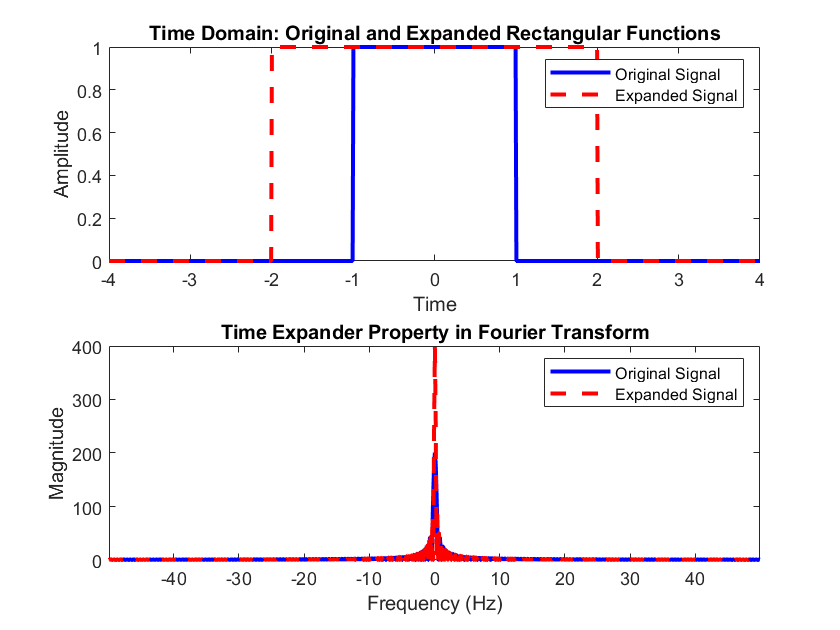

% Time expander property in Fourier transform of rect function

% Define parameters
T = 1;          % Period of the rectangular function
t = linspace(-4*T, 4*T, 800); % Time vector with 800 points
a = 2;          % Stretch factor

% Original rectangular function
x_original = rectangularPulse(-T, T, t);

% Time-expanded rectangular function
x_expanded = rectangularPulse(-a*T, a*T, t);

% Fourier transform of original signal
X_original = fftshift(fft(x_original));

% Fourier transform of expanded signal
X_expanded = fftshift(fft(x_expanded));

% Frequency vector
Fs = 1/(t(2)-t(1)); % Sampling frequency
f = linspace(-Fs/2, Fs/2, length(t));

% Create a new figure
figure;

% Plot the original and expanded signals in the time domain
subplot(2,1,1);
plot(t, x_original, 'b', 'LineWidth', 2);
hold on;
plot(t, x_expanded, 'r--', 'LineWidth', 2);
hold off;
title('Time Domain: Original and Expanded Rectangular Functions');
legend('Original Signal', 'Expanded Signal');
xlabel('Time');
ylabel('Amplitude');
xlim([-4*T, 4*T]); % Set x-axis limits

% Plot the original and expanded signals in the frequency domain
subplot(2,1,2);
plot(f, abs(X_original), 'b', 'LineWidth', 2);
hold on;
plot(f, abs(X_expanded), 'r--', 'LineWidth', 2);
hold off;
title('Frequency Domain: Fourier Transforms');
legend('Original Signal', 'Expanded Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([-Fs/2, Fs/2]); % Set x-axis limits

% Adjust subplot layout
title('Time Expander Property in Fourier Transform', 'FontSize', 14);